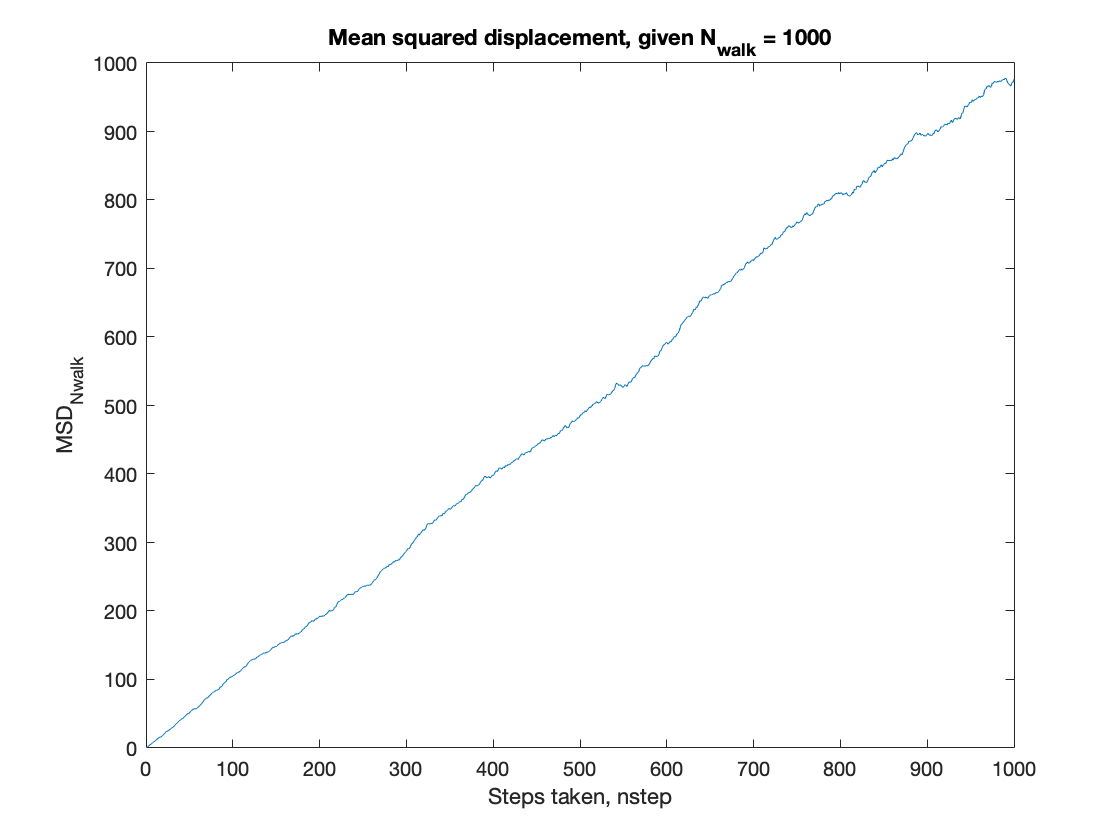

% Random walk and mean square displacement
%
Nwalk=1000;
Nstep=1000;
% Generate Nwalk random walkers that move Nstep steps randomly to the left
% (x=-1) or to the right (x=+1)
x=2*randi(2,Nstep,Nwalk)-3;
% Sum up the steps to measure how they move (displacements/ trajectories)
y=cumsum(x,1);
% plot all the trajectories
%figure(1), plot(y)
%title('All N_{walk} random walkers trajectories')
%xlabel('Steps taken, nstep')
%ylabel('Position relative to start position (displacements)')
% calculate the mean square displacement
%i.e. the mean of all the walkers' squared displacements
msd=mean(y.^2,2);
% plot the msd, slope is 2Dt
figure(2), plot(msd)
title('Mean squared displacement, given N_{walk} = 1000')
xlabel('Steps taken, nstep')
ylabel('MSD_{Nwalk}')

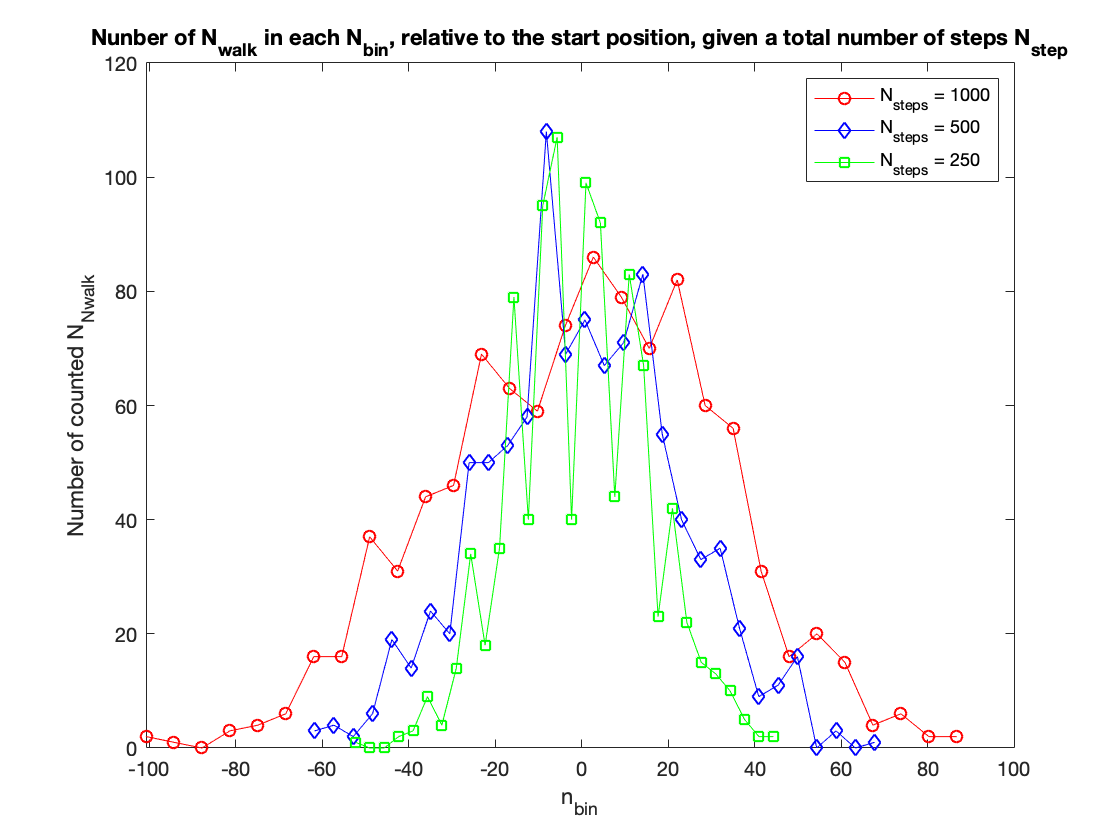


Nbin = 30;
[counts_Ns,centers_Ns]=hist(y(Nstep,:),Nbin);
[counts_Nsh,centers_Nsh]=hist(y(Nstep/2,:),Nbin);
[counts_Nsq,centers_Nsq]=hist(y(Nstep/4,:),Nbin);
figure(3), plot(centers_Ns,counts_Ns,'-or',centers_Nsh,counts_Nsh,'-db',centers_Nsq,counts_Nsq,'-sg')
title('Nunber of N_{walk} in each N_{bin}, relative to the start position, given a total number of steps N_{step}')
xlabel('n_{bin}')
ylabel('Number of counted N_{Nwalk}')
legend('N_{steps} = 1000','N_{steps} = 500','N_{steps} = 250')

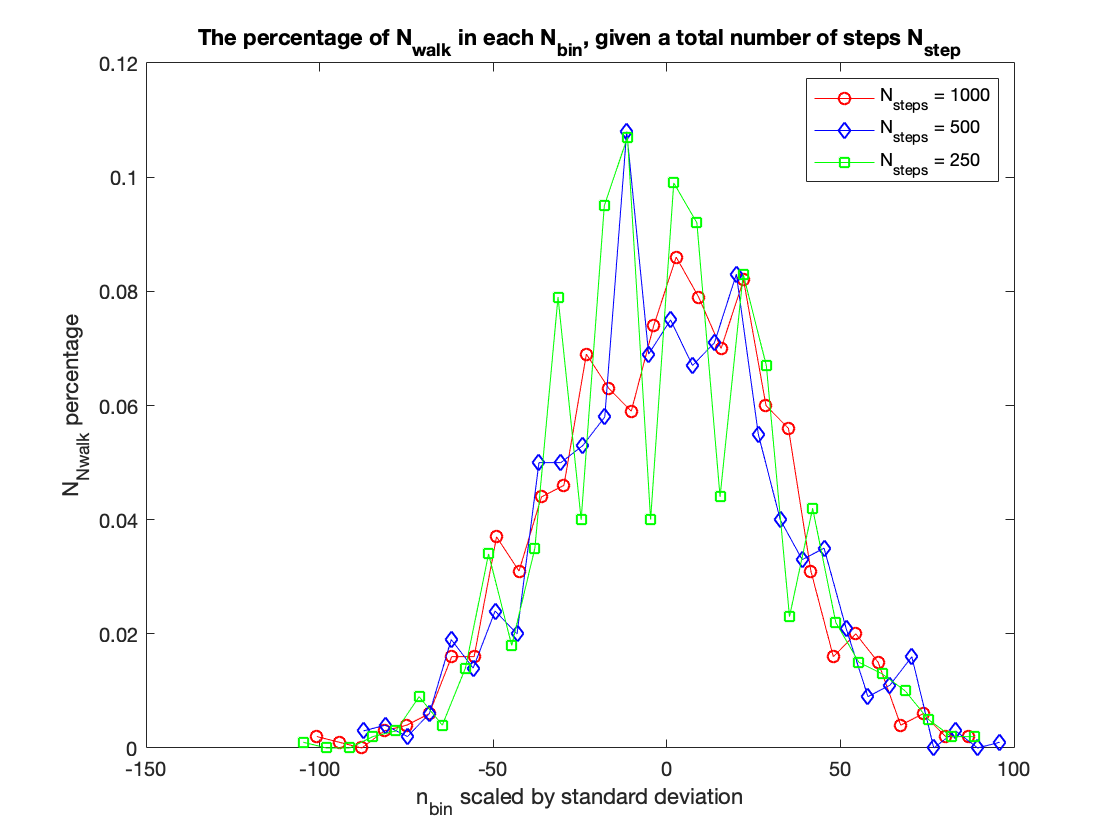


figure(4), plot(centers_Ns,counts_Ns/Nwalk,'-or',centers_Nsh*sqrt(2),counts_Nsh/Nwalk,'-db',centers_Nsq*sqrt(4),counts_Nsq/Nwalk,'-sg')
title('The percentage of N_{walk} in each N_{bin}, given a total number of steps N_{step}')
xlabel('n_{bin} scaled by standard deviation')
ylabel('N_{Nwalk} percentage')
legend('N_{steps} = 1000','N_{steps} = 500','N_{steps} = 250')


% Calculate second moment of distribution = 2Dt
twoDt_Ns = sum(centers_Ns.^2.*counts_Ns)/Nwalk;
twoD_Ns = twoDt_Ns/Nstep

twoD_Ns = 0.9810

twoDt_Nsh = sum(centers_Nsh.^2.*counts_Nsh)/Nwalk; 
twoD_Nsh = twoDt_Nsh/(Nstep/2)

twoD_Nsh = 0.9757

twoDt_Nsq = sum(centers_Nsq.^2.*counts_Nsq)/Nwalk; 
twoD_Nsq = twoDt_Nsq/(Nstep/4)

twoD_Nsq = 0.9449

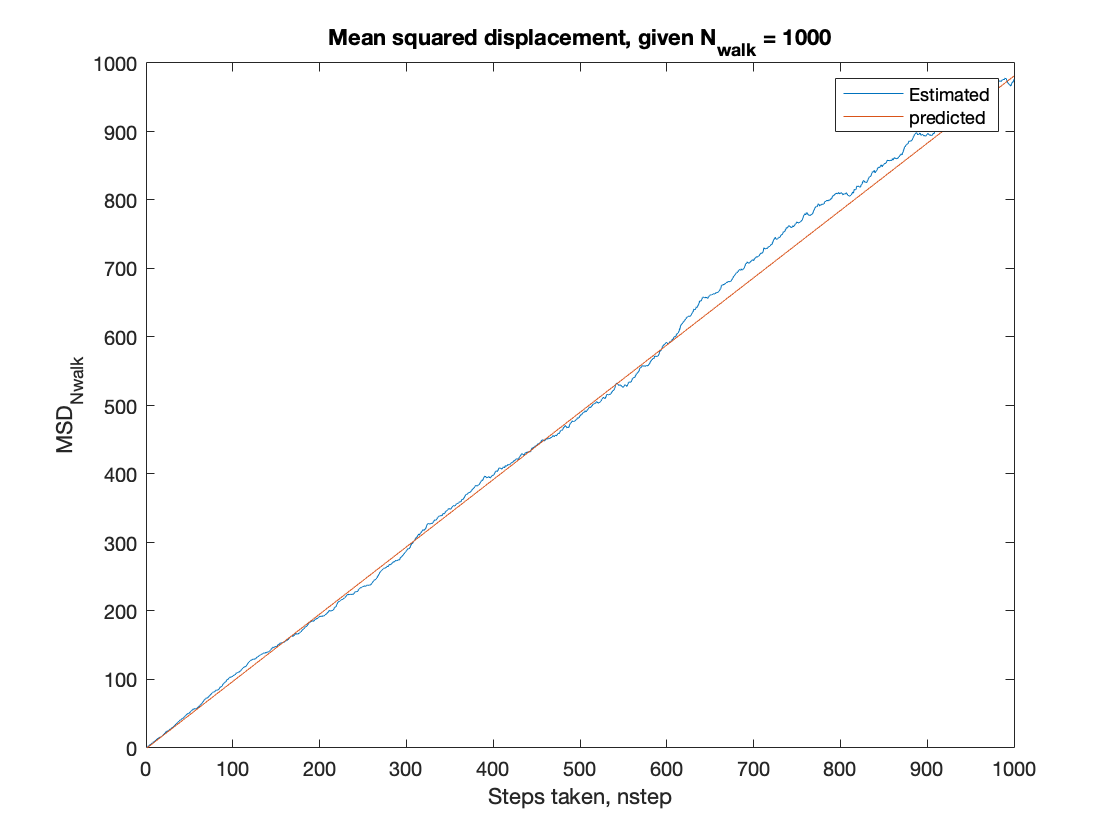

prediction = twoD_Ns*linspace(0,Nstep,Nstep);
figure(5), plot(msd)
title('Mean squared displacement, given N_{walk} = 1000')
xlabel('Steps taken, nstep')
ylabel('MSD_{Nwalk}')
hold on
plot(prediction)
legend('Estimated','predicted')
hold off